% plots data from test_clean_consistency2

% plots biggest contributors to hist as function of min_valids

ij = 1;
biggest = [];
thresh = num_times * 0.2;
dip_means = zeros(1, length(min_valids));
dip_medians = zeros(1, length(min_valids));
dip_sds = zeros(1, length(min_valids));
dip_vols = zeros(1, length(min_valids));
for ii = 1:length(min_valids)
    dip_means(ii) = mean(dips{ii,ij});
    dip_medians(ii) = median(dips{ii,ij});
    dip_sds(ii) = std(dips{ii,ij});
    found = sort(unique(dips{ii,ij}));
    vol = 0;
    for f = found
        len_f = length(find(dips{ii,ij} == f));
        vol = vol + len_f * len_f / num_times / num_times;
        if len_f >= thresh
            biggest = [biggest f];
        end
    end
    dip_vols(ii) = vol;
end
biggest = sort(unique(biggest));
vals = zeros(length(min_valids), length(biggest) + 1);

for ii = 1:length(min_valids)
    tot = 0;
    for i = 1:length(biggest)
        vals(ii,i) = length(find(dips{ii,ij}==biggest(i)));
        tot = tot + vals(ii,i);
    end
    vals(ii, length(biggest) + 1) = num_times - tot;
end

figure();
labels = cell(1,length(biggest));
for i = 1:length(biggest)
    plot(min_valids, vals(:,i));
    labels{i} = num2str(biggest(i));
    hold on
end
plot(min_valids, vals(:,end))
labels{length(biggest)+1} = 'Other';
legend(labels)
title('Histogram vs Min Valids')
xlabel('min valid')
ylabel('num occurrences')

figure();
plot(min_valids, dip_means);
xlabel('min valid');
ylabel('elong estimate')
hold on
plot(min_valids, dip_medians)
legend('mean', 'median');

figure();
yyaxis left
plot(min_valids, dip_sds);
ylabel('sd')
yyaxis right
plot(min_valids, dip_vols);
ylabel('stability')
xlabel('min valids')

figure();
plot(min_valids, [num_traces{:,1}])

% plots as function of min_vals

ij = 1;
biggest = [];
thresh = num_times * 0.1;
for ii = 1:length(min_valids)
    found = sort(unique(dips{ii,ij}));
    for f = found
        if length(find(dips{ii,ij} == f)) >= thresh
            biggest = [biggest f];
        end
    end
end
biggest = sort(unique(biggest));
vals = zeros(length(min_valids), length(biggest) + 1)
for ii = 1:length(min_valids)
    tot = 0;
    for i = 1:length(biggest)
        vals(ii,i) = length(find(dips{ii,ij}==biggest(i)));
        tot = tot + vals(ii,i);
    end
    vals(ii, length(biggest) + 1) = num_times - tot;
end

figure();
labels = cell(1,length(biggest))
for i = 1:length(biggest)
    plot(min_valids, vals(:,i));
    labels{i} = num2str(biggest);
    hold on
end
plot(min_valids, vals(:,end))
labels{length(biggest)+1} = 'Other';
legend(labels)
title('Histogram vs Min Valids')
xlabel('min valid')
ylabel('num occurrences')

ii = 1;
biggest = [];
thresh = num_times * 0.2;
dip_means = zeros(1, length(min_vals));
dip_medians = zeros(1, length(min_vals));
dip_sds = zeros(1, length(min_vals));
dip_vols = zeros(1, length(min_vals));
for ij = 1:length(min_vals)
    dip_means(ij) = mean(dips{ii,ij});
    dip_medians(ij) = median(dips{ii,ij});
    dip_sds(ij) = std(dips{ii,ij});
    found = sort(unique(dips{ii,ij}));
    vol = 0;
    for f = found
        len_f = length(find(dips{ii,ij} == f));
        vol = vol + len_f * len_f / num_times / num_times;
        if len_f >= thresh
            biggest = [biggest f];
        end
    end
    dip_vols(ij) = vol;
end
biggest = sort(unique(biggest));
vals = zeros(length(min_vals), length(biggest) + 1);

for ij = 1:length(min_vals)
    tot = 0;
    for i = 1:length(biggest)
        vals(ij,i) = length(find(dips{ii,ij}==biggest(i)));
        tot = tot + vals(ij,i);
    end
    vals(ij, length(biggest) + 1) = num_times - tot;
end

figure();
labels = cell(1,length(biggest));
for i = 1:length(biggest)
    plot(min_vals, vals(:,i));
    labels{i} = num2str(biggest(i));
    hold on
end
plot(min_vals, vals(:,end))
labels{length(biggest)+1} = 'Other';
legend(labels)
title('Histogram vs Min Valids')
xlabel('min valid')
ylabel('num occurrences')

figure();
plot(min_vals, dip_means);
xlabel('min valid');
ylabel('elong estimate')
hold on
plot(min_vals, dip_medians)
legend('mean', 'median');

figure();
yyaxis left
plot(min_vals, dip_sds);
ylabel('sd')
yyaxis right
plot(min_vals, dip_vols);
ylabel('stability')
xlabel('min valids')

figure();
plot(min_vals, [num_traces{1,:}])

Plots estimated vs real elongation time for test_cleaning.m

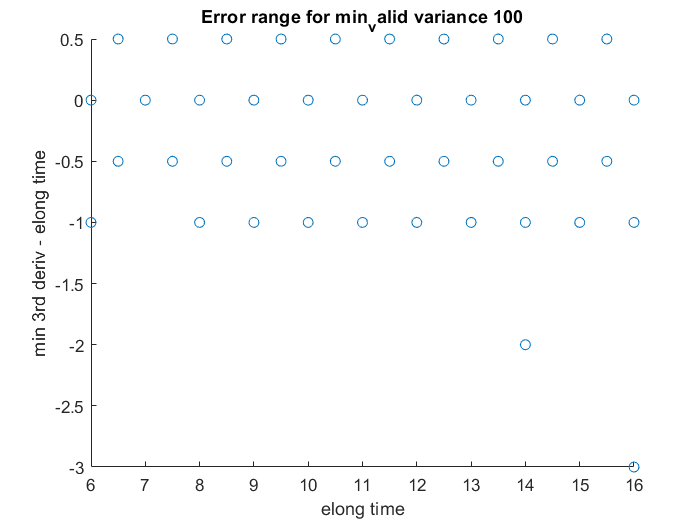

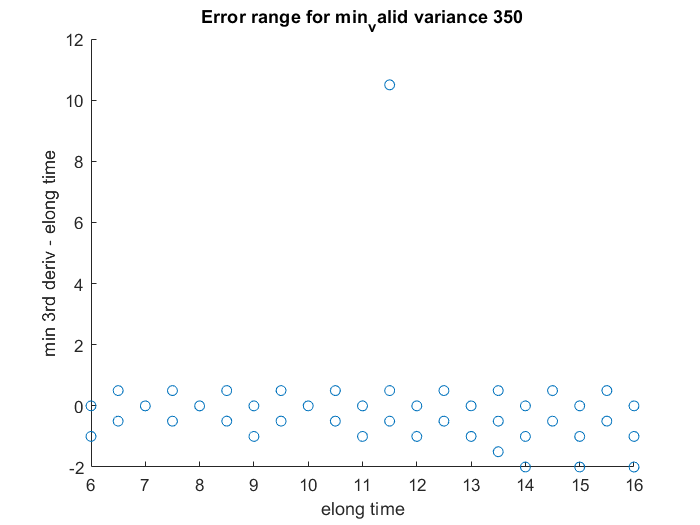

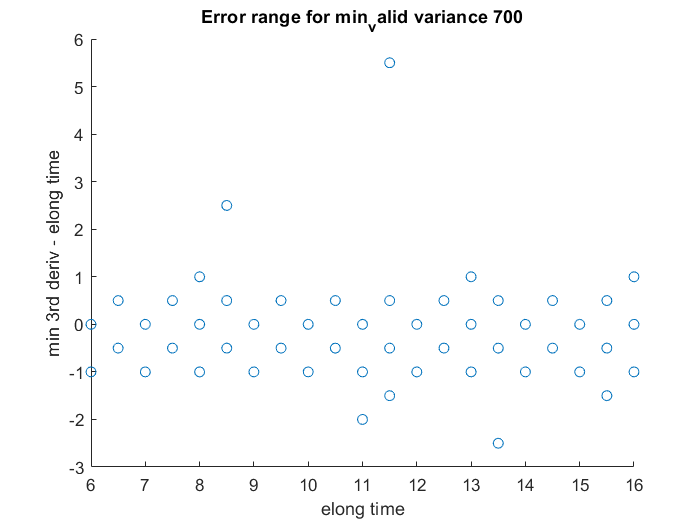

% imports data and makes scatter plots
all_data = load('base_results.mat');
all_data = all_data.all_data;

noises = sort(unique([all_data.noise]));
noise_leg = cell(1, length(noises));
for i = 1:length(noises)   
    noise_leg{i} = int2str(noises(i));
end
vn = 'min_valid';
elongs = sort(unique([all_data.T]));
vars = sort(unique([all_data.(vn)]));

est = 'min3';

% plots 3rd derivative difference from true elongation time
% as function of true elongation time for each noise value
for noise = noises
    noise_data = all_data([all_data.noise] == noise);
    xs = [];
    ys = [];
    for elong = elongs
        elong_data = noise_data([noise_data.T] == elong);
        elong_data = elong_data([elong_data.num_traces] > 100);
        diffs = [elong_data.(est)] - [elong_data.T];
        xs = [xs [elong_data.T]];
        ys = [ys diffs];
    end
    figure()
    scatter(xs, ys);
    xlabel('elong time');
    ylabel(['min 3rd deriv - elong time']);
    title(['Error range for ' vn ' variance ' int2str(noise)])
end

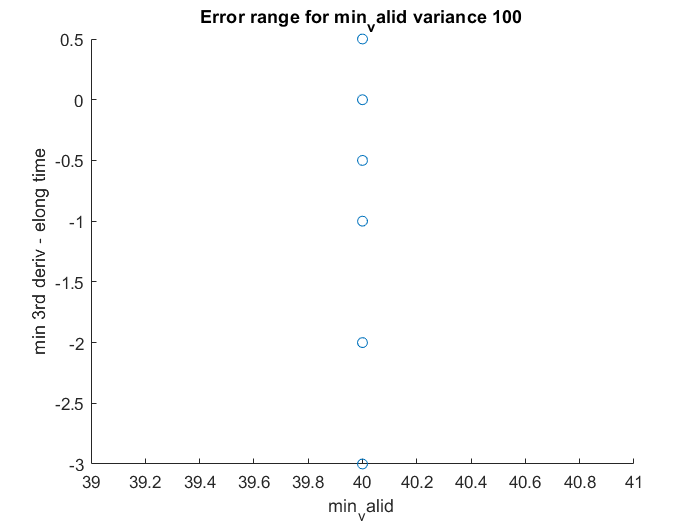

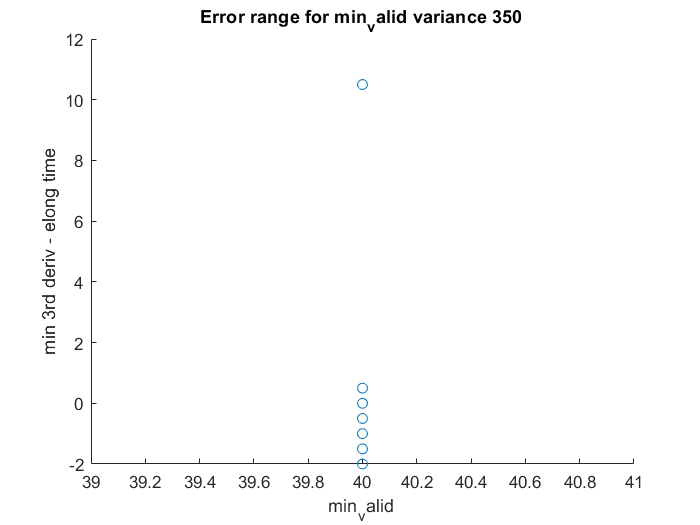

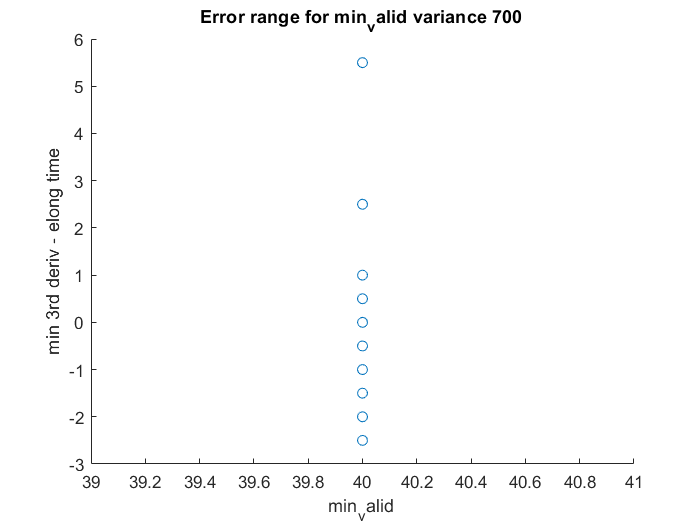



% plots 3rd derivative difference from true elongation time
% as function of the cleaning parameter being varied for each
% noise value
for noise = noises
    noise_data = all_data([all_data.noise] == noise);
    xs = [];
    ys = [];
    for var = vars
        var_data = noise_data([noise_data.(vn)] == var);
        var_data = var_data([var_data.num_traces] > 100);
        diffs = [var_data.(est)] - [var_data.T];
        xs = [xs [var_data.(vn)]];
        ys = [ys diffs];
    end
    figure()
    scatter(xs,ys);
    xlabel(vn);
    ylabel(['min 3rd deriv - elong time']);
    title(['Error range for ' vn ' variance ' int2str(noise)])
end

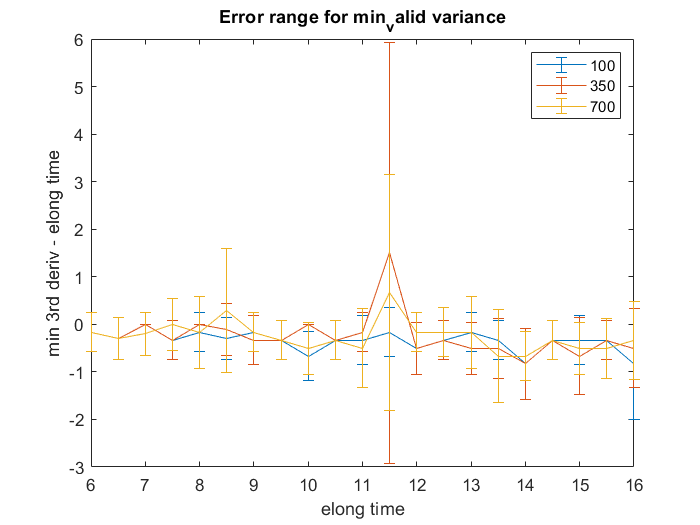

% imports data and makes errorbar plots
all_data = load('base_results.mat');
all_data = all_data.all_data;

noises = sort(unique([all_data.noise]));
noise_leg = cell(1, length(noises));
for i = 1:length(noises)   
    noise_leg{i} = int2str(noises(i));
end
vn = 'min_valid';
elongs = sort(unique([all_data.T]));
vars = sort(unique([all_data.(vn)]));

% plots 3rd derivative difference from true elongation time
% as function of true elongation time for each noise value
figure();
for noise = noises
    noise_data = all_data([all_data.noise] == noise);
    mean_n = [];
    sd_n = [];
    for elong = elongs
        elong_data = noise_data([noise_data.T] == elong);
        elong_data = elong_data([elong_data.num_traces] > 100);
        diffs = [elong_data.(est)] - [elong_data.T];
        mean_n = [mean_n mean(diffs)];
        sd_n = [sd_n std(diffs)];
    end
    errorbar(elongs, mean_n, sd_n);
    hold on
end
xlabel('elong time');
ylabel(['min 3rd deriv - elong time']);
title(['Error range for ' vn ' variance'])
legend(noise_leg);

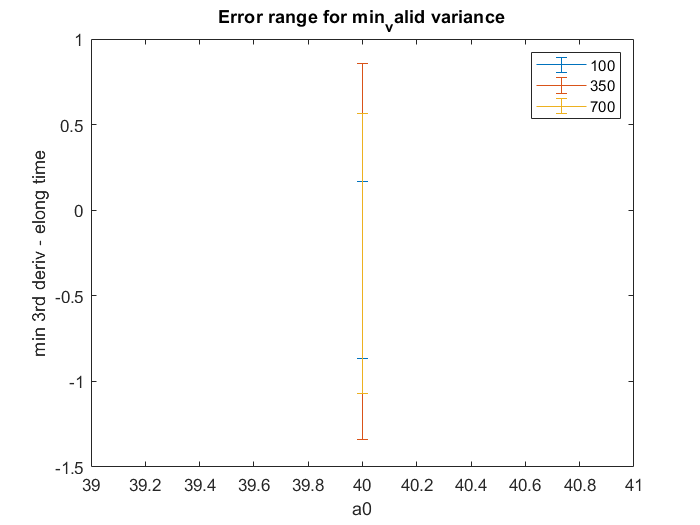


% plots 3rd derivative difference from true elongation time
% as function of the cleaning parameter being varied for each
% noise value
figure()
for noise = noises
    noise_data = all_data([all_data.noise] == noise);
    mean_n = [];
    sd_n = [];
    for var = vars
        var_data = noise_data([noise_data.(vn)] == var);
        var_data = var_data([var_data.num_traces] > 100);
        diffs = [var_data.(est)] - [var_data.T];
        mean_n = [mean_n mean(diffs)];
        sd_n = [sd_n std(diffs)];
    end
    errorbar(vars, mean_n, sd_n);
    hold on
end
xlabel('a0');
ylabel(['min 3rd deriv - elong time']);
title(['Error range for ' vn ' variance'])
legend(noise_leg)

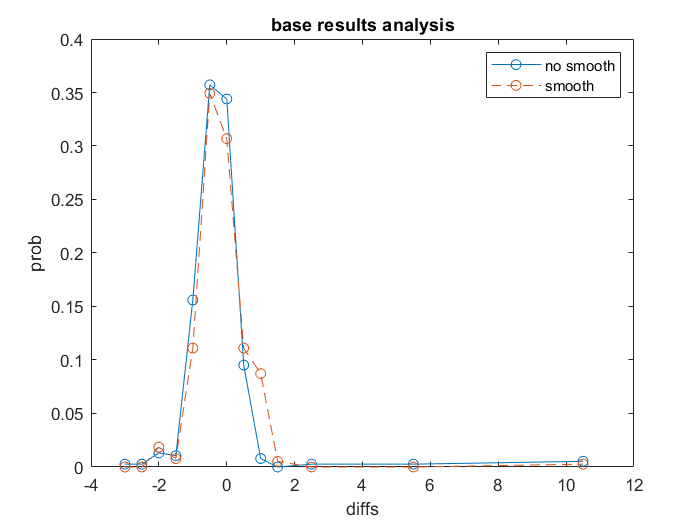

% Probability distribution of diffs
all_data = load('base_results.mat');
all_data = all_data.all_data;

figure();
diffs = [all_data.min3] - [all_data.T];
diffs_smooth = [all_data.min3_s] - [all_data.T];
all_poss = sort(unique([diffs diffs_smooth]));

nums = zeros(1, length(all_poss));
nums_s = zeros(1, length(all_poss));

for i = 1:length(all_poss)
    nums(i) = length(find(diffs == all_poss(i))) / length(diffs);
    nums_s(i) = length(find(diffs_smooth == all_poss(i))) / length(diffs_smooth);
end

figure();
plot(all_poss, nums, 'o-');
hold on
plot(all_poss, nums_s, 'o--');
xlabel('diffs');
ylabel('prob');
title('base results analysis');
legend('no smooth', 'smooth')

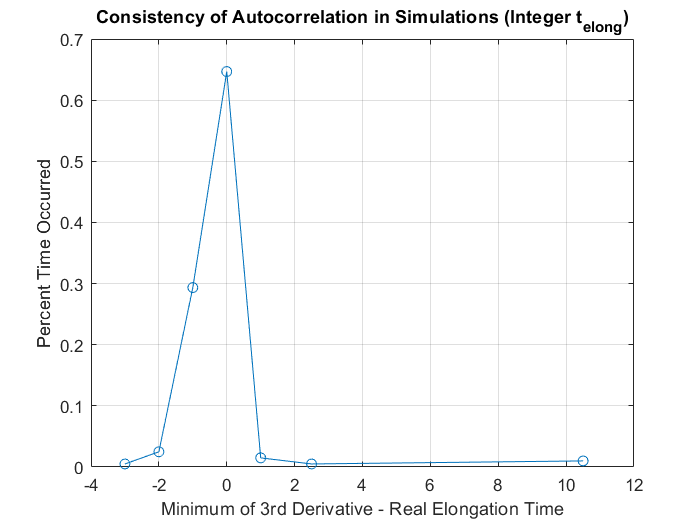


figure()
plot(all_poss(1:2:end), nums(1:2:end) / sum(nums(1:2:end)), '-o');
xlabel('Minimum of 3rd Derivative - Real Elongation Time')
ylabel('Percent Time Occurred')
title('Consistency of Autocorrelation in Simulations (Integer t_{elong})')
grid on

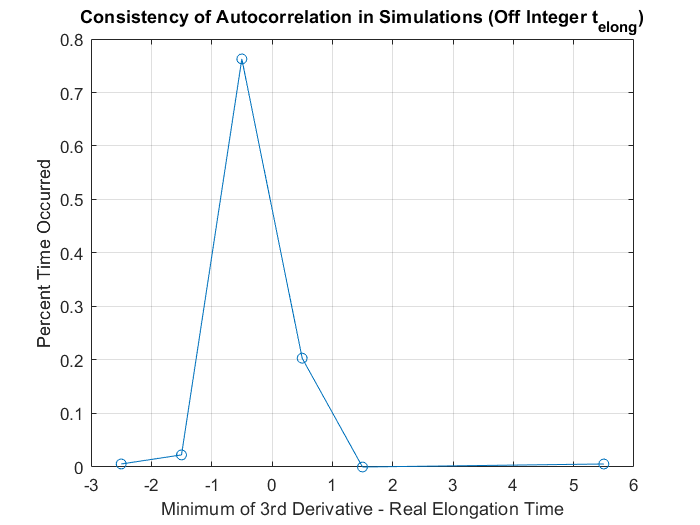

figure()
plot(all_poss(2:2:end), nums(2:2:end) / sum(nums(2:2:end)), '-o');
xlabel('Minimum of 3rd Derivative - Real Elongation Time')
ylabel('Percent Time Occurred')
title('Consistency of Autocorrelation in Simulations (Off Integer t_{elong})')
grid on

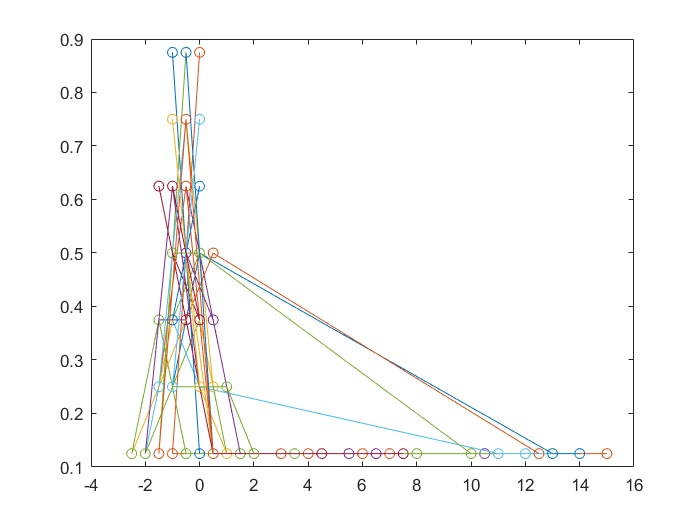

% Looks at how often cleaning parameters change outcome

all_data = load('thresh_results.mat');
all_data = all_data.all_data;

elongs = unique([all_data.T]);
rises = unique([all_data.a0]);
noises = unique([all_data.noise]);
num_diff = 0;
num_count = 0;
figure()
for elong = elongs
    for rise = rises
        for noise = noises(3:3)
            lim_data = all_data([all_data.T] == elong);
            lim_data = lim_data([lim_data.a0] == rise);
            lim_data = lim_data([lim_data.noise] == noise);
            diffs = [lim_data.min3] - [lim_data.T];
            if length(unique(diffs)) > 1
                num_diff = num_diff + 1;
                all_poss = sort(unique(diffs));
                nums = zeros(1, length(all_poss));
                for i = 1:length(all_poss)
                    nums(i) = length(find(diffs == all_poss(i))) / length(diffs);
                end
                plot(all_poss, nums, 'o-')
                hold on
            end
            num_count = num_count + 1;
        end
    end
end